# European Put - Naive Quadrature

%% Part 1 – Naive European Quadrature (no T–h smoothing)
clear; clc;

function price = european_quad_naive(S0,K,r,q,sigma,T,n_steps,m_grid)
    % Time step and grid 
    h   = T / n_steps;
    s0  = log(S0);
    smin = s0 - 10*sigma*sqrt(T);
    smax = s0 + 10*sigma*sqrt(T);
    s    = linspace(smin,smax,m_grid)'; 
    S    = exp(s);
    mid  = ceil(m_grid/2);
    ds   = s(2) - s(1);

    % Simpson weights (1 4 2 4 ... 2 4 1)
    w = ones(m_grid,1);
    w(2:2:end-1)=4; w(3:2:end-2)=2;
    w = w*(ds/3);

    % Terminal payoff 
    v_next = max(K - S, 0);
    disc   = exp(-r*h);

    % Backward recursion
    for t = 1:n_steps
        % recompute transition density each step (inefficient)
        mu_shift = (r - q - 0.5*sigma^2)*h;
        sig_h    = sigma*sqrt(h);
        F = zeros(m_grid);
        for i = 1:m_grid
            mu_i = s(i) + mu_shift;
            z = (s' - mu_i)/sig_h;
            F(i,:) = (1/(sig_h*sqrt(2*pi))) * exp(-0.5*z.^2);
        end
        % continuation value (no max)
        v_next = disc * (F * (v_next .* w));
    end

    price = v_next(mid);
end

% Run a test 
tic;
S0=50; K=50; r=0.05; q=0.02; sigma=0.30;
T=60/365; n_steps=60; m_grid=401;
price = european_quad_naive(S0,K,r,q,sigma,T,n_steps,m_grid);
fprintf('Naive European Put Price (no T–h smoothing): %.6f\n',price);

Naive European Put Price (no T–h smoothing): 2.290223


toc;

Elapsed time is 0.134220 seconds.


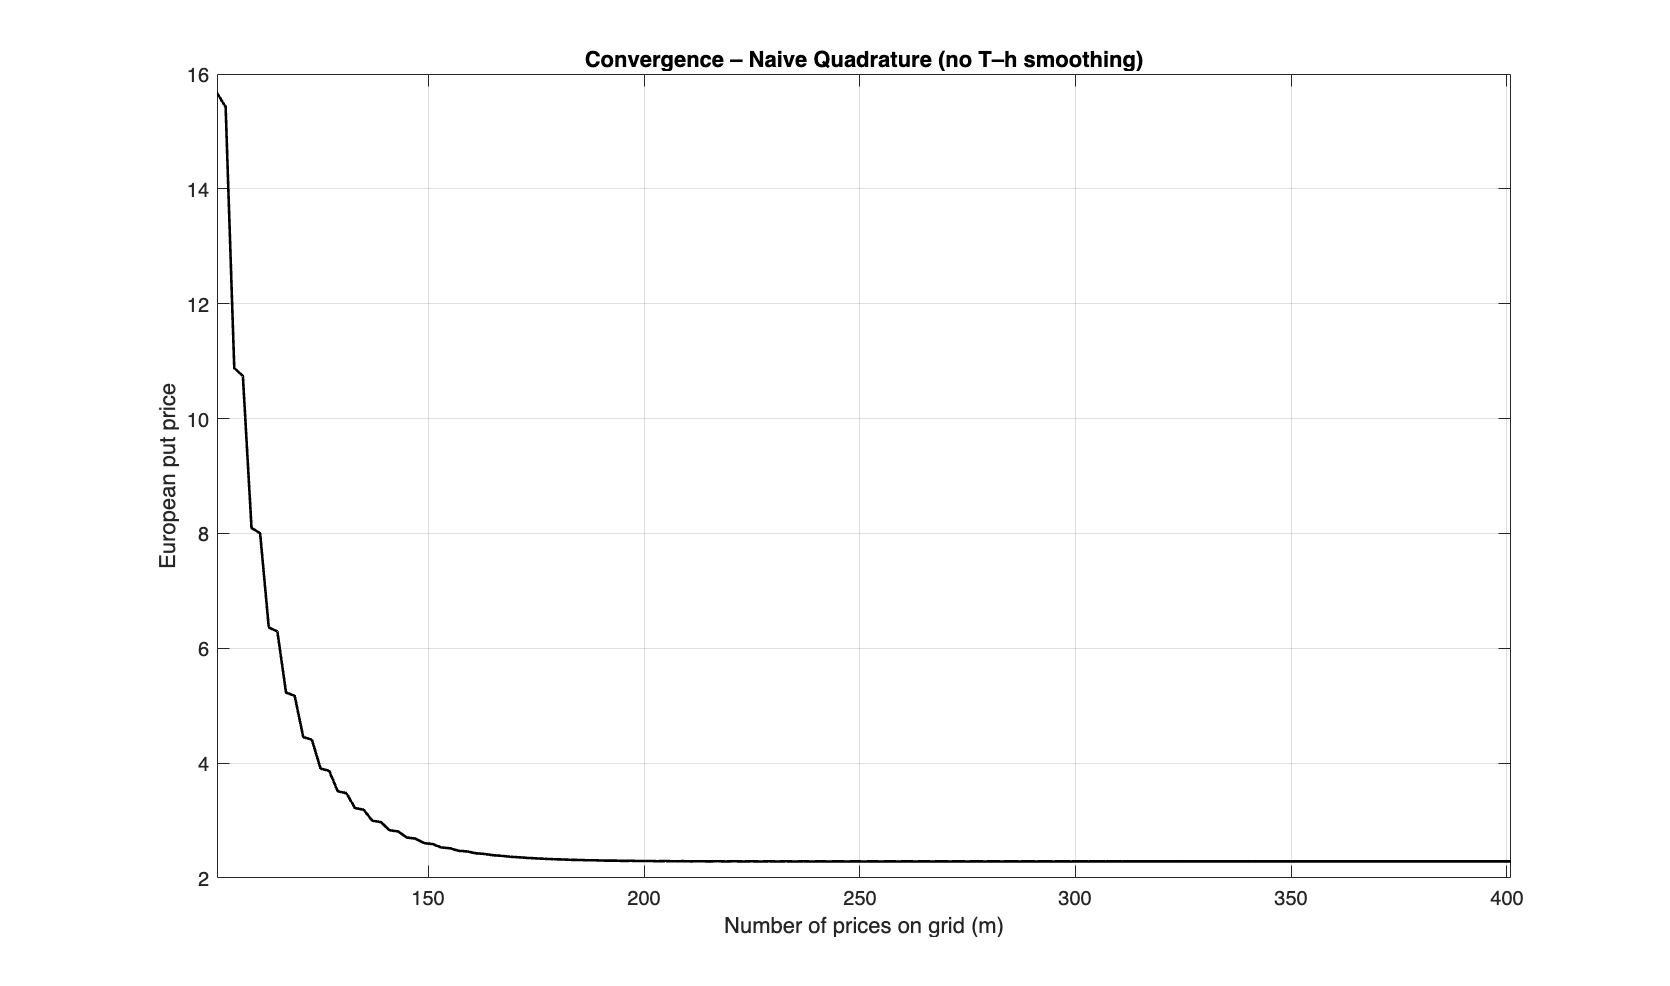


% Convergence sweep 
m_list = 101:2:m_grid;
prices = nan(size(m_list));
for k = 1:numel(m_list)
    prices(k) = european_quad_naive(S0,K,r,q,sigma,T,n_steps,m_list(k));
end

% Plot:
figure; hold on; box on;
plot(m_list, prices,'k-','LineWidth',1.3);
xlabel('Number of prices on grid (m)');
ylabel('European put price');
title('Convergence – Naive Quadrature (no T–h smoothing)');
grid on; xlim([min(m_list) max(m_list)]);